%Q1
%%(1)
H1 = tf([1],[1,1]);
H1

H1 =
 
    1
  -----
  s + 1
 
连续时间传递函数。
模型属性



zeros1 = zero(H1);
disp('零点是');

零点是


zeros1


zeros1 =

  空的 0×1 double 列向量




poles1 = pole(H1);
disp('极点是');

极点是


poles1

poles1 = -1



%%(2)
H2 = tf([10],[1,-5,0]);
H2

H2 =
 
     10
  ---------
  s^2 - 5 s
 
连续时间传递函数。
模型属性


%{
zeros2 = zero(H2);
disp('零点是');
zeros2

poles2 = pole(H2);
disp('极点是');
poles2
%}
[p, z] = pzmap(H2)

p =      0
     5



z =

  空的 0×1 double 列向量



%Q2
%(1)
num1 = [3 -9 6];
den1 = [1 3 2];
H1 = tf(num1,den1);
[p1,z1] = pzmap(H1)

p1 =     -2
    -1


z1 =      2
     1


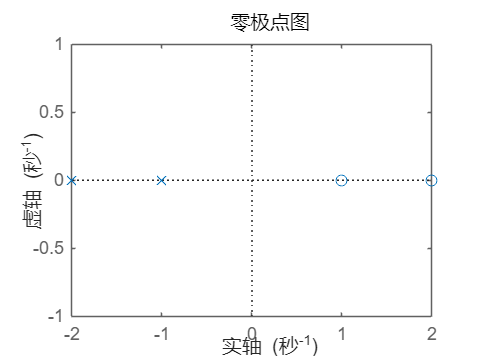

pzmap(H1)


%(2)
num2 = [0 1];
den2 = [1 0];
H2 = tf(num2,den2);
[p2,z2] = pzmap(H2)

p2 = 0


z2 =

  空的 0×1 double 列向量



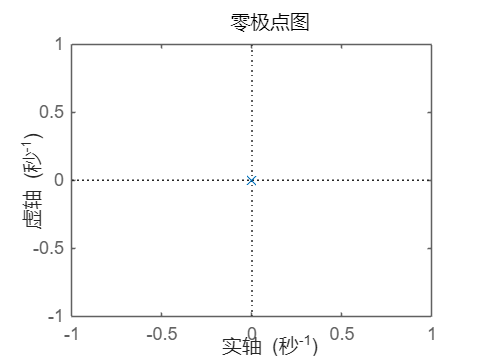

pzmap(H2)


%(3)
num3 = [1.8, 1.2, 1.2, 3];
den3 = [1 3 2 1];
H3 = tf(num3,den3);
[z3,p3] = tf2zp(num3,den3)

z3 =   -1.2284 + 0.0000i
   0.2809 + 1.1304i
   0.2809 - 1.1304i


p3 =   -2.3247 + 0.0000i
  -0.3376 + 0.5623i
  -0.3376 - 0.5623i


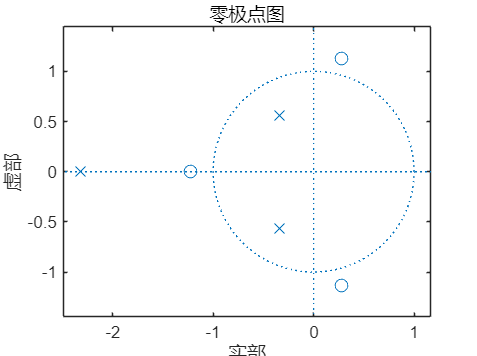

%z3 = roots(num3)
zplane(num3,den3)

%Q3
%(1)
A = [2 2 1;
     1 3 1;
     1 2 2];
poles = eig(A)

poles =     5.0000
    1.0000
    1.0000



B = [3;3;4];
C = [1 0 0;0 1 0;0 0 1];
D = 0;
iu =1;

C1 = [1 0 0];
[z1, p1,k1] = ss2zp(A,B,C1,D,iu)

z1 =     1.0000
    0.6667


p1 =     5.0000
    1.0000
    1.0000


k1 = 3

disp(' ');


C2 = [0 1 0];
[z2, p2, k2] = ss2zp(A, B, C2, D, iu)

z2 =     0.6667
    1.0000


p2 =     5.0000
    1.0000
    1.0000


k2 = 3

disp(' ');


C3 = [0 0 1];
[z3, p3, k3] = ss2zp(A, B, C3, D, iu)

z3 =     1.0000
    1.7500


p3 =     5.0000
    1.0000
    1.0000


k3 = 4.0000

disp(' ');


pole_real = real(poles);
if all(pole_real < 0)
    disp('稳定')
elseif any(pole_real > 0)
        disp('不稳定');
else 
    disp('临界稳定');
end

不稳定



%(2)
num = conv([1, -1.414, 1],[1,1]);
den = conv([1, 0.9, 0.81],[1,-0.3]);

z1 = roots(num)

z1 =   -1.0000 + 0.0000i
   0.7070 + 0.7072i
   0.7070 - 0.7072i


p1 = roots(den)

p1 =   -0.4500 + 0.7794i
  -0.4500 - 0.7794i
   0.3000 + 0.0000i



pole_mag = abs(p1);
if all(pole_mag < 1)
    disp('稳定');
elseif any(pole_mag > 1)
    disp('不稳定');
else
    disp('临界稳定');
end

稳定


%Q4
%(1)
a = 5;  
b = 8;
c = 10;


routh = zeros(4, 2);  
routh(1,1) = 1;       
routh(1,2) = b;       


routh(2,1) = a;       
routh(2,2) = c;       


routh(3,1) = (a*b - 1*c)/a;  
routh(3,2) = 0;              


routh(4,1) = c;
routh(4,2) = 0;


disp('劳斯表（第一列）：');

劳斯表（第一列）：


disp(routh(:,1)); 

     1
     5
     6
    10




if all(sign(routh(:,1)) == sign(routh(1,1)))
   disp('系统稳定');
else
    disp('系统不稳定');
end

系统稳定



%(2)
a = 1;  
b = 6;
c = 8;
d = 1;


routh = zeros(5, 2);  
routh(1,1) = 1;       
routh(1,2) = b;       
routh(2,1) = a;       
routh(2,2) = c;  
routh(3,1) = (a*b - 1*c)/a;
routh(4,1) = (routh(3,1)*c - a*d)/routh(3,1);
routh(5,1) = d;


disp('劳斯表（第一列）：');

劳斯表（第一列）：


disp(routh(:,1)); 

    1.0000
    1.0000
   -2.0000
    8.5000
    1.0000




if all(sign(routh(:,1)) == sign(routh(1,1)))
    disp('系统稳定');
else
    disp('系统不稳定');
end

系统不稳定



%Q3
a = 1;  
b = 2;
c = 2;
d = 3;


routh = zeros(5, 2);  
routh(1,1) = 1;       
routh(1,2) = b;       
routh(2,1) = a;       
routh(2,2) = c;  
routh(3,1) = (a*b - 1*c)/a;
routh(4,1) = (routh(3,1)*c - a*d)/routh(3,1);
routh(5,1) = d;


disp('劳斯表（第一列）：');

劳斯表（第一列）：


disp(routh(:,1)); 

     1
     1
     0
  -Inf
     3




if all(sign(routh(:,1)) == sign(routh(1,1)))
    disp('系统稳定');
else
    disp('系统不稳定');
end

系统不稳定
